# Multicriteria decision analysis for wind resource assessment and environmental impact

## **Summary**

Multicriteria decision analysis (MCDA) is a useful tool  in the sustainable management and planning of wind energy projects. MDCA aims to find balance between maximising resource utilisation and  minimising environmental impacts. This tutorial uses the Analytic Hierarchy Process (AHP) as a MDCA tool. It is applied to assess site suitability for offshore wind energy project. The study is inspired by Solbrekke and Sorteberg (2024)

**Reference**

Solbrekke, I. M., & Sorteberg, A. (2024). Norwegian offshore wind  power—Spatial planning using multi‐criteria decision analysis. *Wind Energy*, *27*(1), 5-32. 

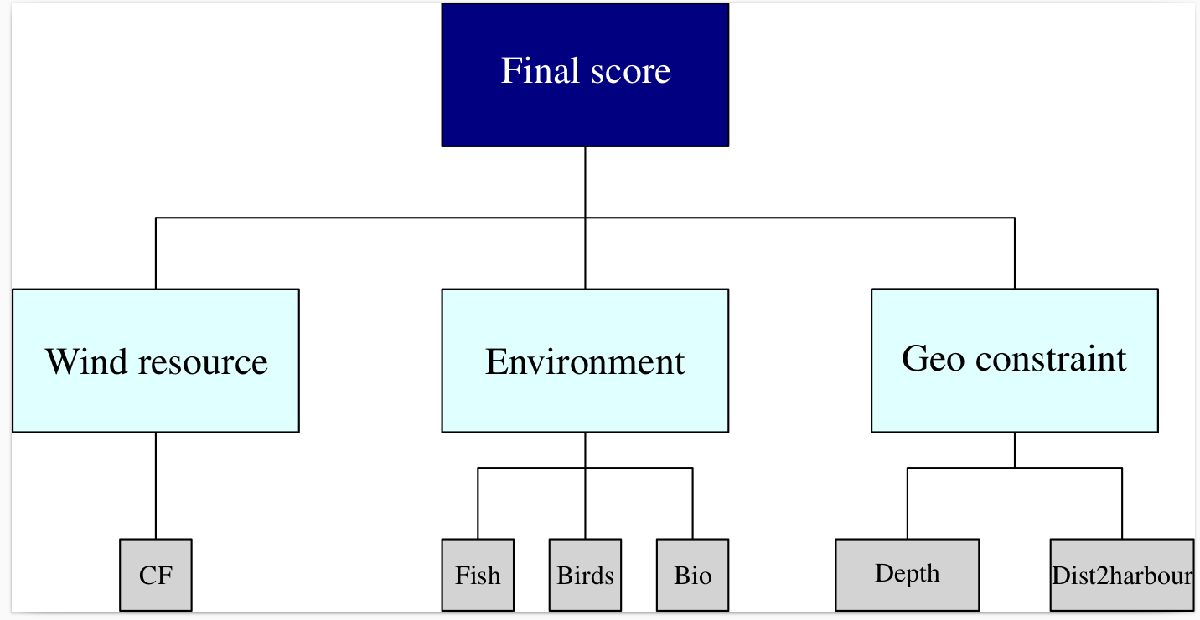

## Setting weights to the main criteria and subcriteria

### main criteria

The decision-making process is  guided by three primary criteria: geographical constraints (Geo),  environmental considerations, and wind resource potential. Each  criterion is evaluated using specific data arrays and weighted to  reflect its relative importance in the overall assessment.

Entering the name of the criteria and subcriteria MUST be in a correct order, following the rows of the weighting matrix. In the present case, it is:

- Wind resource

- Environment

- Geographical constraint 

**Geographical Constraints (Geo)**: The geographical  criteria are quantified using a [652x1149x2] data array. It includes  factors such as depth and distance to the coast. 

**Environmental Considerations**: Environmental impacts are assessed through a [652x1149x3] data array, representing biodiversity,  bird, and fish populations. 

**Wind Resource Potential**: The assessment of wind  resource potential utilises a [652x1149] data array, focusing on the  capacity factor as a measure of the energy a wind farm is expected to  produce. 

clearvars;close all;clc;
addpath('./functions')
N = 3;

% Row 1: wind resource
% Row 2: environment
% Row 3: Geographical constraint

% name of the main criteria
C = {'windResource','environment','Geo'};
uppTri = eye(N);
uppTri(1,1:end) = [1 2 1]; % m1  Wind resource
uppTri(2,2:end) = [1 1]; % m4  environmental considerations
ui= 1./(uppTri);
ui(isinf(ui))= 0;
Criteria.weight = uppTri + transpose(ui) - eye(N);
disp(normalizeWeight(Criteria.weight))

    0.4126
    0.2599
    0.3275



### Sub criteria for wind resource

% Only one criterion
Criteria.(C{1}).weight = 1;

### Sub criteria for environment

% Row 1: biodiversity 
% Row 2: bird 
% Row 3: fish 

N = 3;
uppTri = eye(N);
uppTri(1,1:end) = [1 1 1]; % m1  Wind resource
uppTri(2,2:end) = [1 1]; % m4  environmental considerations
ui= 1./(uppTri);
ui(isinf(ui))= 0;
Criteria.(C{2}).weight = uppTri + transpose(ui) - eye(N);

disp(normalizeWeight(Criteria.(C{2}).weight))

    0.3333
    0.3333
    0.3333



### Sub criteria for geographical constraints

N = 2;
uppTri = eye(N);

% Row 1: Depth
% Row 2: distance to the coast
uppTri(1,1:end) = [1 3]; 
ui= 1./(uppTri);
ui(isinf(ui))= 0;
Criteria.(C{3}).weight = uppTri + transpose(ui) - eye(N);

disp(normalizeWeight(Criteria.(C{3}).weight))

    0.7500
    0.2500



## Preparing the data

 This step involves loading a dataset that flags locations as either inside (`in=1`) or outside (`in=0`) the Norwegian EEZ. 

% Load data indicating whether points are inside or outside the Norwegian EEZ
load('./data/flag_EEZ.mat','in','on')
% 'in' variable indicates: 1 for inside the EEZ, 0 for outside the EEZ


### Data for wind resource

Wind resource data, specifically the capacity factor from the third layer of the `CF` dataset, is normalized and filtered to exclude points outside the Norwegian EEZ. 

% Load averaged wind data
load('./data/averaged_windData.mat', 'CF')

% Normalise and filter capacity factor data based on EEZ
a1 = normalizeVar(CF);
a1(in==0) = nan;
data.(C{1})(:,:,1) = a1; % Capacity factor represented by 'a1'

### Data for the environment

Environmental data for biodiversity, birds, and fish are loaded,  normalized, and filtered to consider only the locations within the EEZ. 

% Load and normalize data for protected areas
load('./data/protected_areas.mat','flag_bio', 'flag_bird', 'flag_fish')

a1 = normalizeVar(flag_bio); % Biodiversity
a2 = normalizeVar(flag_bird); % Bird populations
a3 = normalizeVar(flag_fish); % Fish populations

% Exclude data points outside the EEZ
a1(in==0) = nan;
a2(in==0) = nan;
a3(in==0) = nan;


% Store normalized data in the data structure
data.(C{2})(:,:,1) = a1; % Biological diversity
data.(C{2})(:,:,2) = a2; % Bird nesting and coastal zones
data.(C{2})(:,:,3) = a3; % Fish and spawning grounds

### Data for geographical constraint

For geographical constraints, bathymetry data (depth) and distance to  the nearest coast are processed and normalized, reflecting suitability  for wind turbine installation. Locations with lower depth (shallow  waters) and shorter distance to the coast are considered more suitable.  Data points outside the EEZ are excluded to maintain focus on relevant  areas.

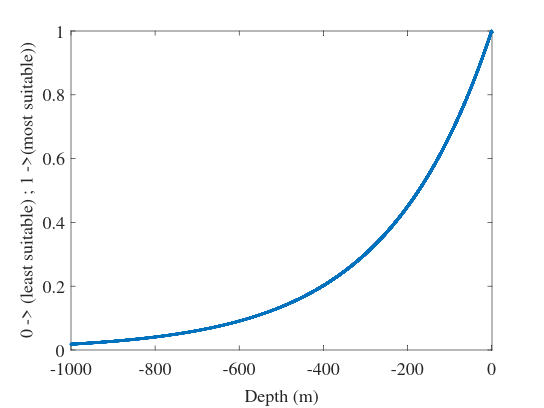

% Load and process bathymetry data for depth analysis
load('./data/bathymetry.mat','lat','lon','z')
z0 = z;
z(z>0) = 1;
z = exp(-abs(z)/250);
z = normalizeVar(z);
z(in==0) = nan;

% Load and normalize distance to coast data
load('./data/dist2Coast.mat', 'dist2Coast')
d = dist2Coast;
d = exp(-d/100);
d = normalizeVar(d);
d(in==0) = nan;

% Store processed data for depth and distance to coast
data.(C{3})(:,:,1) = z; % Depth suitability
data.(C{3})(:,:,2) = d; % Distance to coast suitability

clf;close all;plot(z0(:),z(:),'.');hold on;
xlim([-1000 1])
xlabel('Depth (m)');
ylabel('0 -> (least suitable) ; 1 ->(most suitable))')
set(gcf,'color','w')
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')

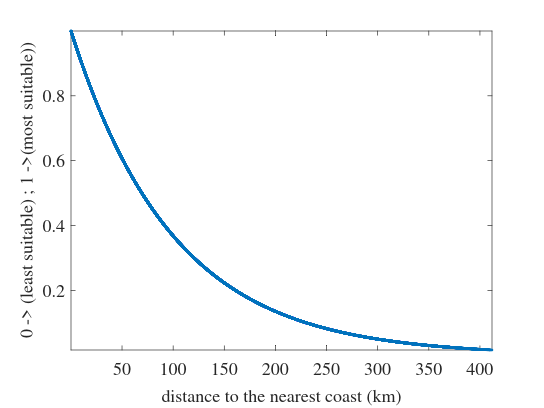


clf;close all;plot(dist2Coast(:),d(:),'.');hold on;
xlabel('distance to the nearest coast (km)');
ylabel('0 -> (least suitable) ; 1 ->(most suitable))')
set(gcf,'color','w')
axis tight
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')

## Run the simulation

printstruct(Criteria)

Criteria
   |    
   |--- Geo
   |       |    
   |       |            -------------------------
   |       |-- weight : |  1.00e+00 |  3.00e+00 |
   |       |            |  3.33e-01 |  1.00e+00 |
   |       |            -------------------------
   |    
   |--- environment
   |       |    
   |       |            -------------------------------------
   |       |-- weight : |  1.00e+00 |  1.00e+00 |  1.00e+00 |
   |       |            |  1.00e+00 |  1.00e+00 |  1.00e+00 |
   |       |            |  1.00e+00 |  1.00e+00 |  1.00e+00 |
   |       |            -------------------------------------
   |    
   |--- windResource
   |       |    
   |       |-- weight : 1
   |    
   |                  -------------------------------------
   |-------- weight : |  1.00e+00 |  2.00e+00 |  1.00e+00 |
   |                  |  5.00e-01 |  1.00e+00 |  1.00e+00 |
   |                  |  1.00e+00 |  1.00e+00 |  1.00e+00 |
   |                  -------------------------------------


printstruct(data)

data
   |    
   |----------- Geo : [652x1149x2 Array]
   |--- environment : [652x1149x3 Array]
   |-- windResource : [652x1149 Array]


tic
[score] = getFinalScore(data,Criteria);
toc

Elapsed time is 0.055687 seconds.


Remove some forbidden locations

load('./data/bathymetry.mat','lat','lon','z')
depth = z; clear z
load('data/dist2Coast.mat', 'dist2Coast')
% score(depth<-1000) = 0; % Any score with a depth larger than 1000 m is set to zero(deemed unfeasible in the present case)
score(dist2Coast<5) = 0; % It is assumed it is forbidden to build turbines less than 5 km from the coastline
score(in==0) = nan; % Remove score outside the EEZ

### Visualize the score

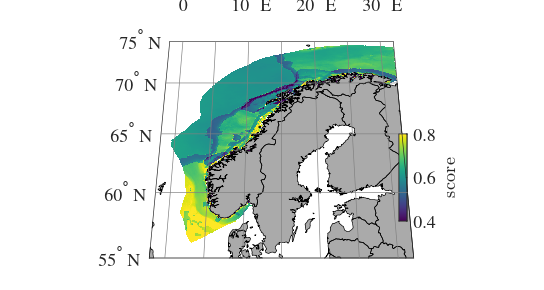

set(0, 'DefaultFigureRenderer', 'painters');
clf;close all;
figure('Position',[500  578         750         400])
myProjection = 'eckert2';
% worldmap([55, 74],[-2 32])
ha=axesm(myProjection,'MapLonLimit',[-2 32],'MapLatLimit',[55, 75]);
geoshow(lat,lon,score, 'DisplayType','surface','CData',score,'ZData',0.*score)
hold on
bordersm('countries','facecolor',.666*[1 1 1])
colormap('viridis');
clim([0.4 0.8])
cb2 = colorbar('location','east');
x1=get(gca,'position');x=get(cb2,'Position');x(1)=x(1)+0.01;x(2)=x(2)+0.1;x(3)=0.015; x(4)=0.3;set(cb2,'Position',x);set(gca,'position',x1)
cb2.Label.String = 'score';
cb2.Label.Interpreter = 'latex';
cb2.AxisLocation = 'out';
% set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

axis off
% setm(gca, 'meridianlabel', 'on', 'parallellabel', 'on')
set(gcf,'color','w')

% get the position of the first axes
L = get(ha, 'Position');

% make a new axes in the same position
axes('Position', L)

axesm (myProjection,...
    'MapLonLimit',[-2 32],'MapLatLimit',[55, 75],...
    'Frame', 'on',...
    'FLineWidth', 0.5,...
    'Grid', 'on',...
    'GLineStyle', '-',...
    'GLineWidth', 0.5,...
    'GColor', [.5 .5 .5], ...
    'MLineLocation', 5,...
    'MLabelLocation', 10,...
    'PLineLocation', 5,...
    'PLabelLocation', 5);

mlabel on;
plabel on;
axis off;

set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')
exportgraphics(gcf,'score_ENERGI230.pdf','ContentType','auto')